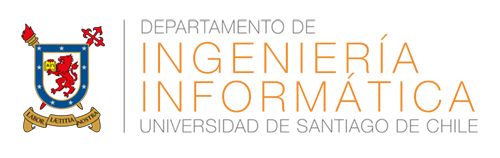

# Tarea N° 4

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Profesores:

- Violeta Chang C.

- Alejandro Catalán.

Ayudante: Luis Corral

# Generales

 Precaución al reproducir las señales, archivos wav o sus resultados en audífonos o altavoces ya que puede ocasionar daño a su sistema de reproducción o más importante a sus oídos. 

Entregue un archivo .mlx de Matlab sin ningún adjunto (archivos .wav, archivos .m ni otros). Se evalúa los conceptos y fórmulas en formato de texto, los comentarios dentro del código, la exactitud y simpleza del algoritmo y la calidad de los gráficos generados. Muestre solo los valores más importantes.

# Problema

El ruido de *feedback* se produce cuando un sistema de amplificación, por ejemplo una cadena micrófono-amplificador-altavoz, se retroalimenta. Esto significa que el sonido que emite el altavoz es captado por el micrófono y amplificado nuevamente. Dependiendo de la distancia entre el micrófono y el altavoz el *feedback* contiene solo una componente de frecuencia que puede estar a lo largo de todo el rango audible entre 20 Hz y 20000 Hz. A menos que el encargado del sistema de amplificación tenga oído absoluto, la herramienta más útil para eliminar este ruido es el espectro de frecuencias mediante la transformada de Fourier.

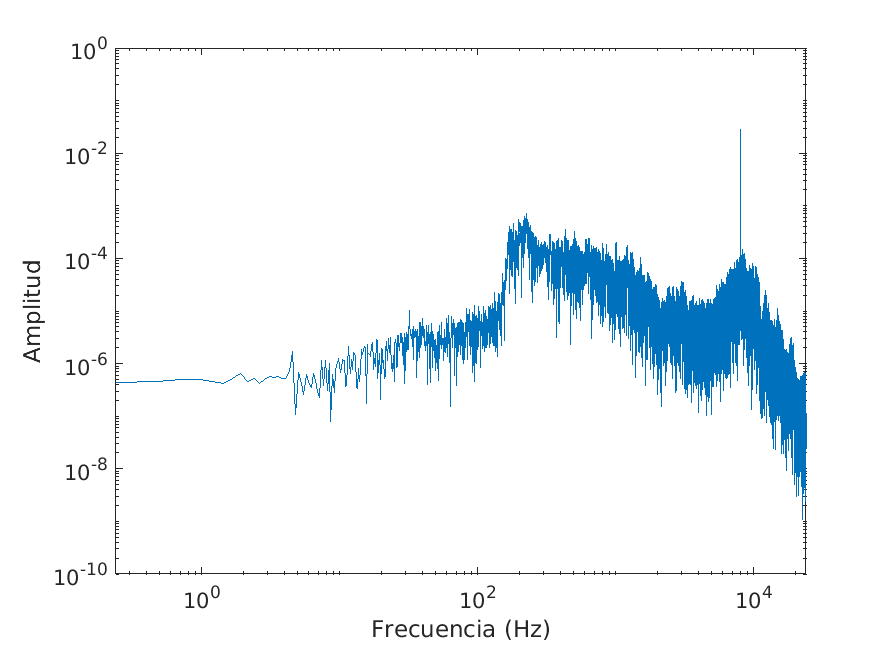

**Figura 1: Espectro de frecuencias de una señal de voz con ruido de *****feedback*****.**

Los audios 'audioX.wav' con X de 1:1:10 contienen señales de voz contaminadas con ruido de *feedback* en distintas frecuencias. La tarea consiste en determinar el valor de la frecuencia de *feedback* y eliminarla de la señal mediante un filtro *notch*. Se adjunta el diseño y aplicación del filtro donde f_notch es la frecuencia a la que se ha determinado que corresponde el ruido de *feedback*.

clearvars
[y,Fs] = audioread('audio11.wav');
f_notch = 8000;
filt = design(fdesign.notch('N,F0,Q',4,f_notch,6.5,Fs),'Systemobject',true);
yf = filt(y);

Puede escuchar el resultado antes y después de la aplicación del filtro para verificar su eficacia. 

% Con ruido
player = audioplayer(y, Fs);
playblocking(player)

% Sin ruido
player = audioplayer(yf, Fs);
playblocking(player)

Diseñe su programa para que reciba la entrada de solo un archivo de audio, grafique el espectro de frecuencias antes y luego de aplicado el filtro. 

# Referencias

[1] [https://salford.figshare.com/articles/media/Speech_corpus_-_Harvard_-_raw_audio/7862666?file=14640254](https://salford.figshare.com/articles/media/Speech_corpus_-_Harvard_-_raw_audio/7862666?file=14640254)

[2] [https://service.shure.com/s/article/how-do-i-fix-my-feedback-problem?language=es](https://service.shure.com/s/article/how-do-i-fix-my-feedback-problem?language=es)

[3] [https://hub.europe.yamaha.com/article/o%C3%ADdo-absoluto-%C2%BFen-qu%C3%A9-consiste-realmente](https://hub.europe.yamaha.com/article/o%C3%ADdo-absoluto-%C2%BFen-qu%C3%A9-consiste-realmente)